# Ch. 3: Square waves and Gibbs' Phenomenon

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

In this demo we'll consider the Fourier series expansion of the square wave and observe Gibbs' phenomenon.

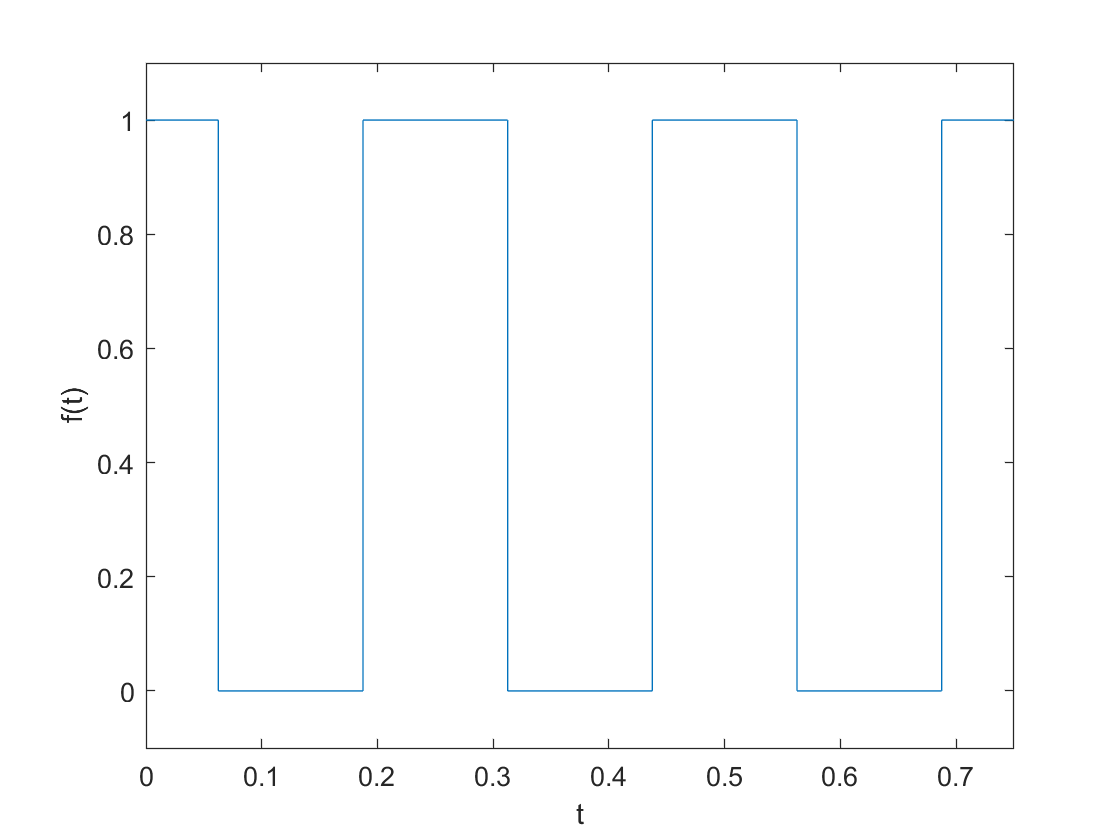

SAMPLE_RATE = 44100; %Per usual, use the sample rate of an audio CD
DURATION = 1;
tValues = linspace(0,DURATION,SAMPLE_RATE*DURATION);
f = 4; %frequency of the square wave

x = 1/2*square(2*pi*f*(tValues+1/(4*f)),50) + 1/2; %MATLAB outputs an even square wave; let's make it odd to be consistent with the notes.

%Let's plot three periods of the square wave
plot(tValues(1:round(3/f*SAMPLE_RATE)),x(1:round(3/f*SAMPLE_RATE)));
xlabel('t');
ylabel('f(t)');
axis([-inf inf -0.1 1.1]);

Next, let's compute the Fourier series expansion of the square wave. For finitely many series components, we'll plot the reconstruction alongside the true signal.

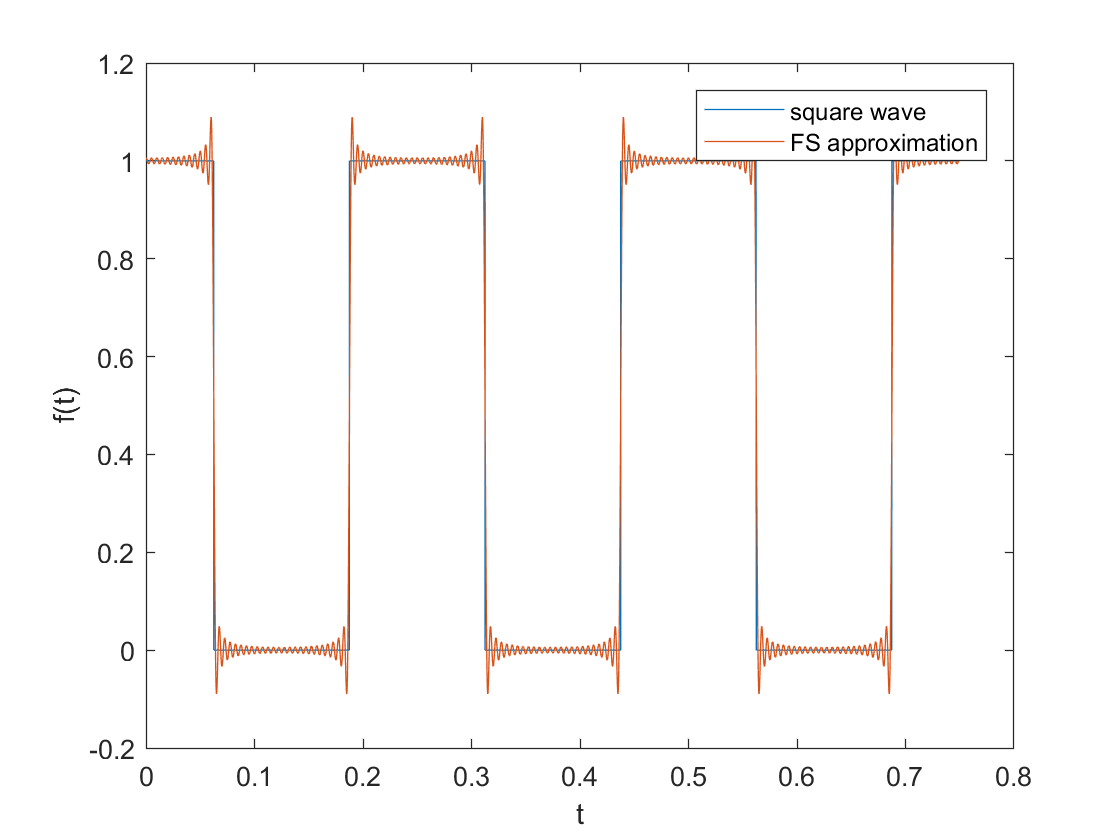

k = 50;

xFS = 1/2*ones(1,SAMPLE_RATE*DURATION); %the DC component is 1/2

for i=1:2:k %Square wave FS coefficients are zero except for odd values
    Di = 1/pi*sin(i*pi/2)/i; %this is the FS coefficient Di and D-i (why?!);
    
    xFS = xFS + Di*exp(sqrt(-1)*2*pi*i*f*tValues) + Di*exp(-sqrt(-1)*2*pi*i*f*tValues);
end %for k

plot(tValues(1:round(3/f*SAMPLE_RATE)),x(1:round(3/f*SAMPLE_RATE)),tValues(1:round(3/f*SAMPLE_RATE)),xFS(1:round(3/f*SAMPLE_RATE)));
xlabel('t');
ylabel('f(t)');
legend('square wave','FS approximation');